h = 6.626e-34;
cavity_temp = 3;
amp_noise_photons_at_input_to_chain = 4;
kb = 1.38e-23;
res_freq = 5.785e9;
kerr = 0.35e6;
kappa_ext = 1.2e6;
kappa_int = 0; % kappa_int assumed 0 in Wustmann PRB sec VIID
kappa_tot = kappa_ext + kappa_int;
flux_pump_to_damping_rate_ratio = 2;
flux_pump = flux_pump_to_damping_rate_ratio * kappa_tot/2;
pump_detuning = 9e6;
rotating_frame_freq = (res_freq - pump_detuning)

rotating_frame_freq = 5.7760e+09

pump_freq = 2 * (res_freq - pump_detuning);
sa_span = 30e6;
res_BW = 1;
freqs_around_pump_over_2 = linspace(-sa_span/2, sa_span/2, 1000);

%%% classical parametric oscillation oscillation amp %%%
if pump_detuning > sqrt(flux_pump^2 - kappa_tot^2/4)
    cavity_amp = 0 % units of photon number
elseif sqrt(flux_pump^2 - kappa_tot^2/4) > pump_detuning
    cavity_amp = 1/kerr *(-pump_detuning + sqrt(flux_pump^2 - kappa_tot^2/4)) %units of photon number
else 
    cavity_amp = 0
end

cavity_amp = 0

%%% quantum fluctuation quantities
ksi_tilde = pump_detuning + 2*kerr*cavity_amp;
flux_pump_tilde = flux_pump + kerr*cavity_amp;
determinant = (kappa_tot/2 - 1i.*freqs_around_pump_over_2).^2 + ksi_tilde.^2 - flux_pump_tilde^2;

See Wustmann PRB eqn 99

%%%% power spectrum
cavity_temp_factor = (exp(h*res_freq/kb/cavity_temp) + 1)/ (exp(h*res_freq/kb/cavity_temp) - 1);
power_at_omega = flux_pump_tilde.^2 * kappa_tot^2 ./ abs(determinant).^2;
added_noise_photons_at_amp_input = ones(size(freqs_around_pump_over_2)) .* amp_noise_photons_at_input_to_chain * h .* ...
    (freqs_around_pump_over_2 + res_freq + pump_detuning);

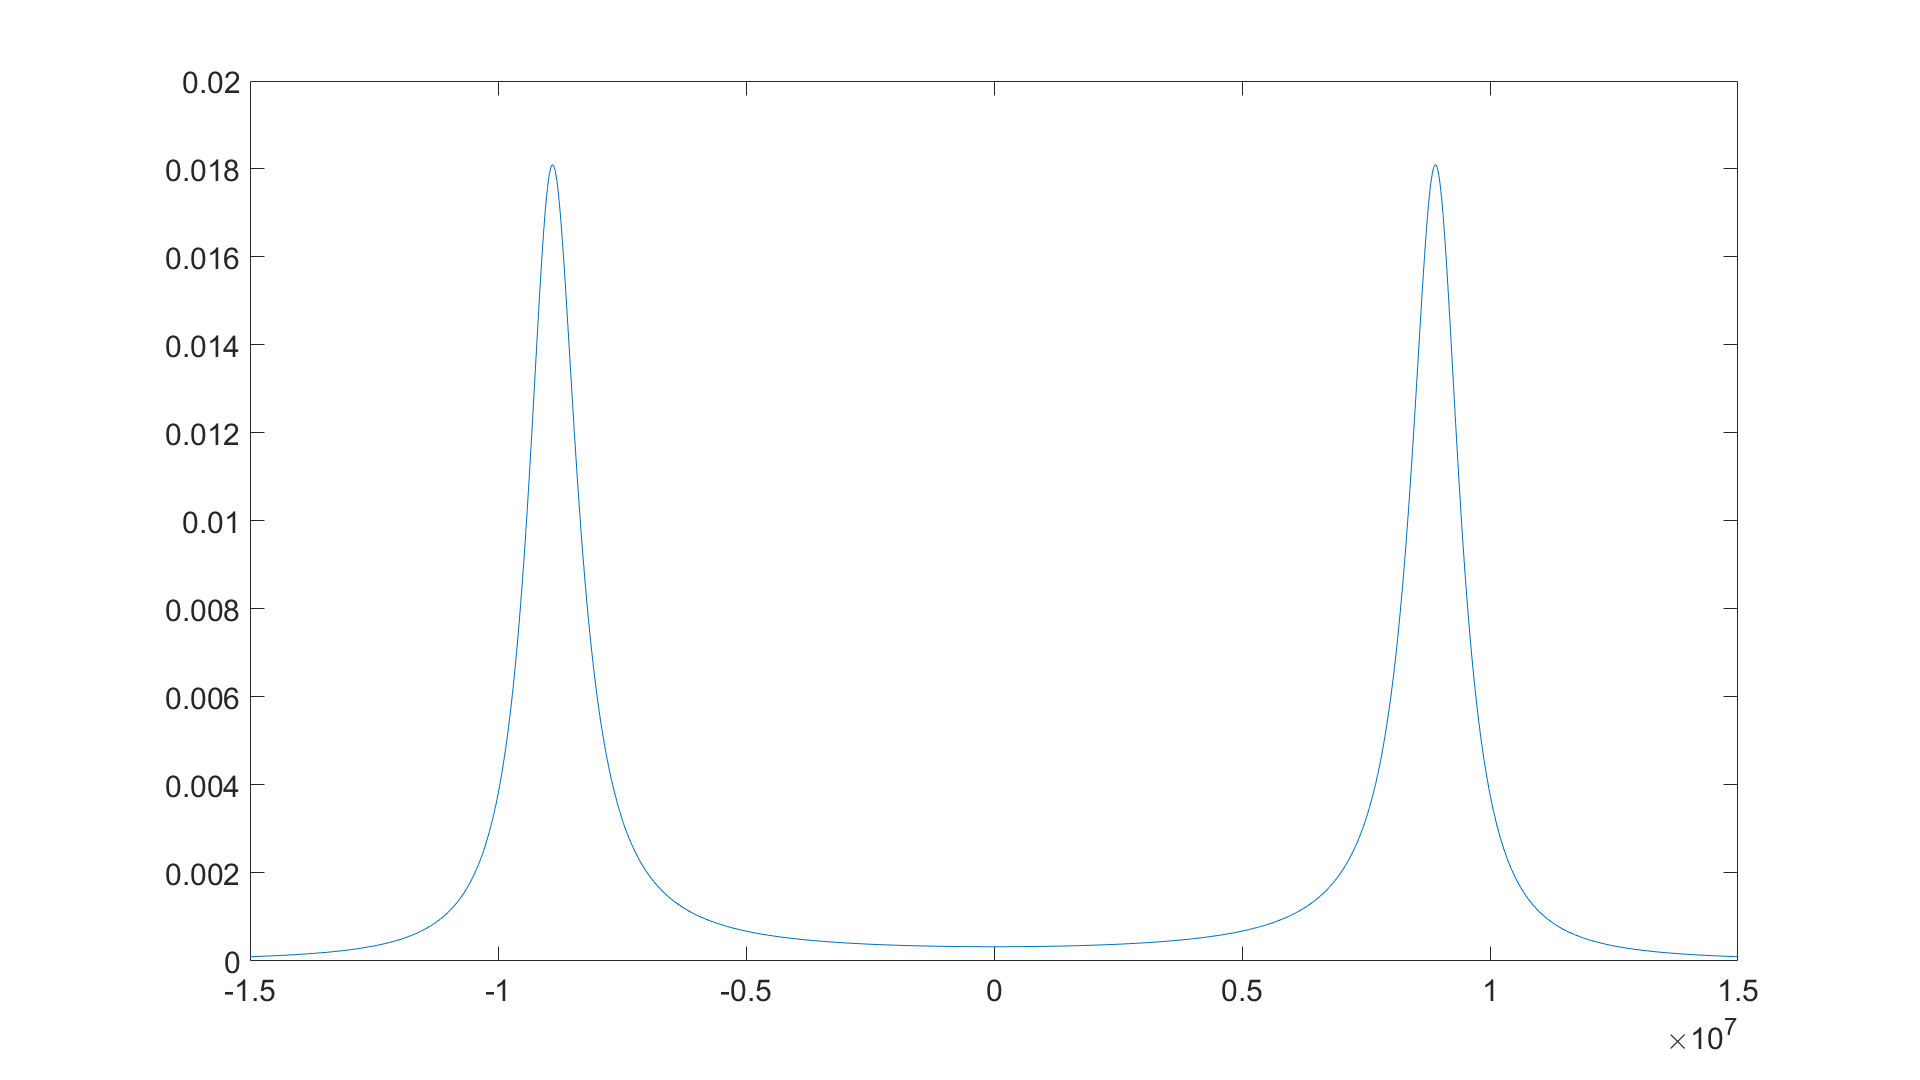

figure
plot(freqs_around_pump_over_2, power_at_omega)

% hold on
% plot(freqs_around_pump_over_2, h*res_freq*added_noise_photons_at_amp_input)

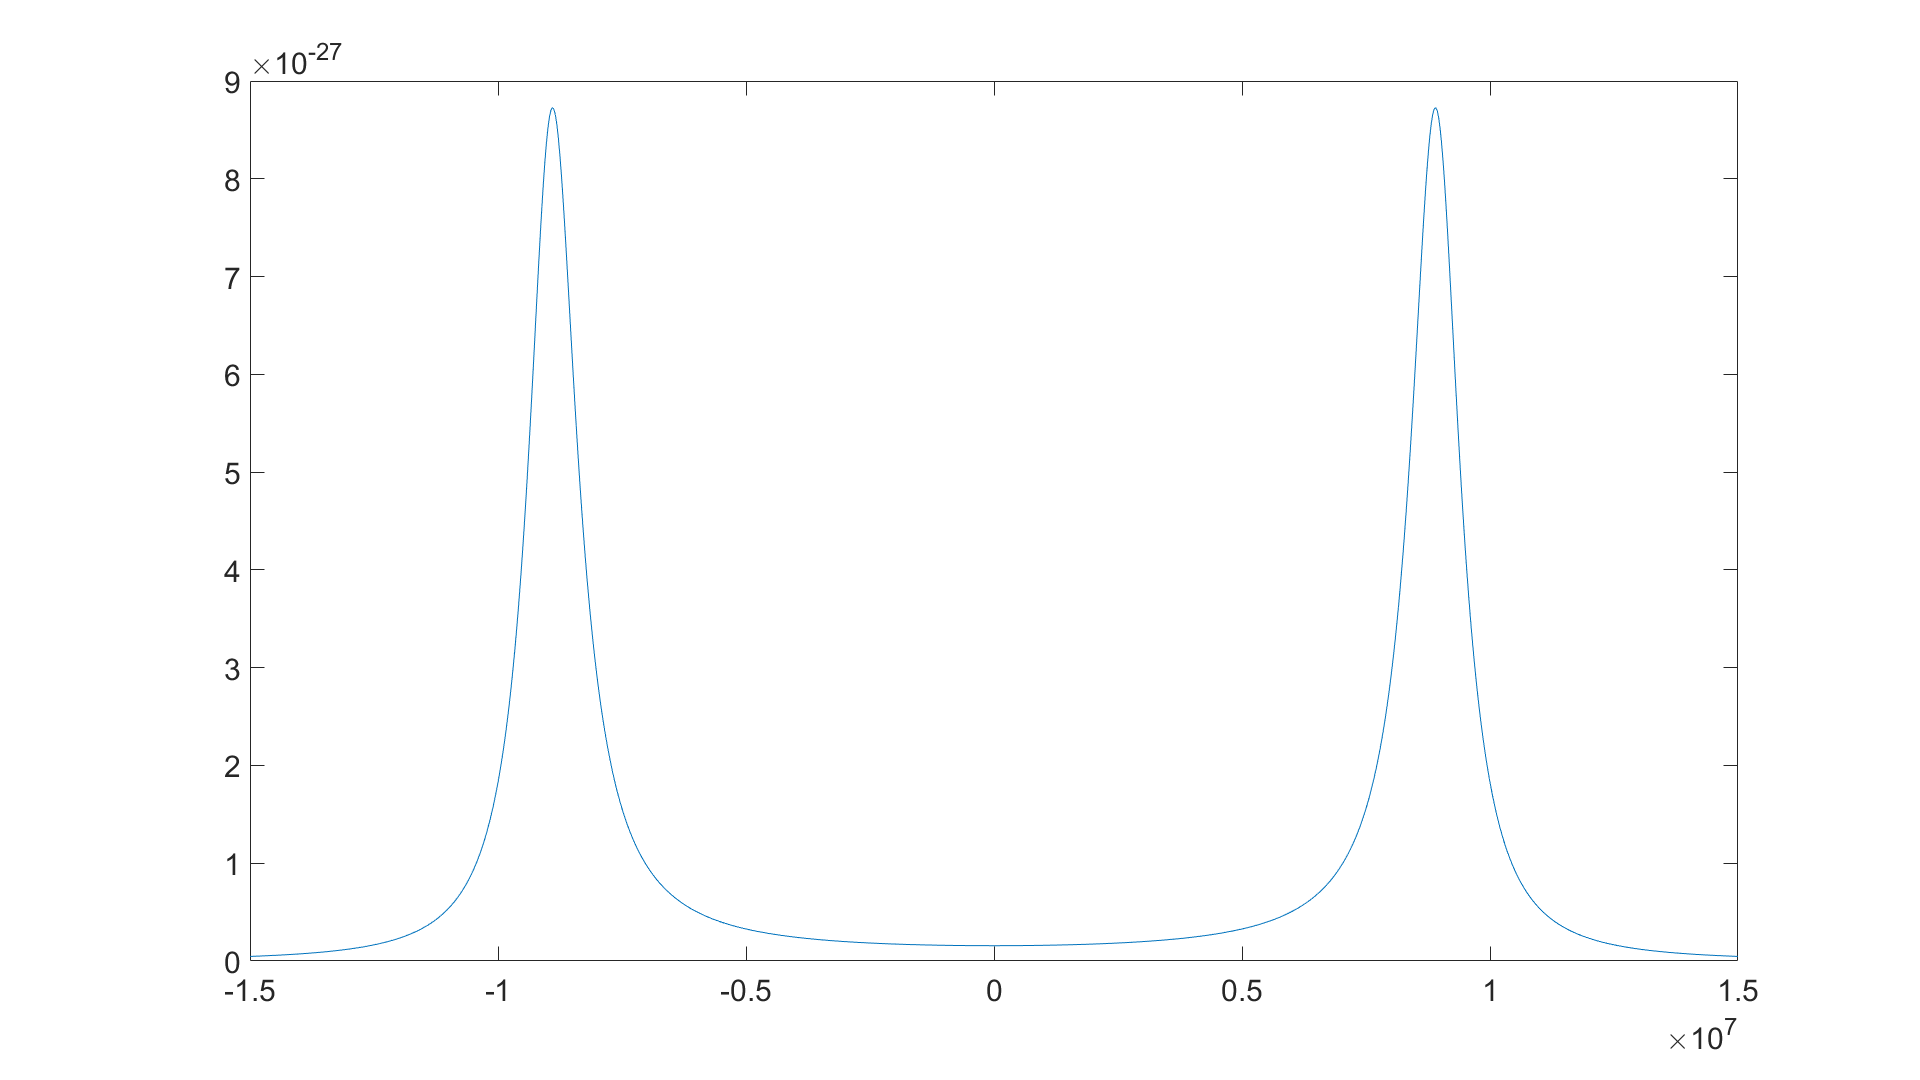

figure
plot(freqs_around_pump_over_2, 1./(abs(determinant)).^2)

sqrt(flux_pump_tilde ^2 - kappa_tot^2/4)

ans = 1.0392e+06